# Reduced-Order Modeling Technique for System-Level Simulation of Aircraft Wing Spar

This example shows how to run system-level simulations by using the Descriptor State-Space block to implement a reduced-order model of the I-beam in an aircraft wing spar.

- First, develop the finite-element model of the 3-D I-beam using the Partial Differential Equation Toolbox.

- Then, use the Craig-Bampton reduced-order modeling (ROM) technique to reduce the finite-element model to have fewer degrees of freedom (DoFs).

- Derive the coefficients for the A, B, C, D, and E matrices from the ROM of the I-beam for use in the Descriptor State-Space block.

- Model the loading forces, including the coupling of the wing spar deflection, in Simulink using lookup tables.

- Simulate the beam deflection and loading forces by running a parameter sweep across different angles of attack and free-stream velocities.

- Using the loading forces from the worst-case system-level simulation, solve the full finite-element model and compare the results to the ROM simulation results

## Beam Geometry

 Define the key geometric parameters of the I-beam.

tw = 0.015; % Thickness of the web
hw = 0.09; % Height of the web
tf = 0.02; % Thickness of the flange
wf = 0.08; % Width of the flange
spanOfBeam = 1.5;

Create a geometry representing the cross-section of the I-beam, composed of rectangles for the web and flanges, both centered on the y-axis. 

Define the rectangles for the web. The web section of the I-beam cross-section has four faces split along the symmetric axes. Subdividing the web into such sections provides geometric vertices at the mid-web section where lumped lift, drag, and twisting loads are applied.

tw_sub = tw/2; % Subdivided thickness/width for each rectangle
hw_sub = hw/2; % Subdivided height for each rectangle

R1 = [3;4;-tw_sub;0;0;-tw_sub;-hw_sub;-hw_sub;0;0]; % bottom left
R2 = [3;4;0;tw_sub;tw_sub;0;-hw_sub;-hw_sub;0;0]; % bottom right
R3 = [3;4;-tw_sub;0;0;-tw_sub;0;0;hw_sub;hw_sub]; % top left
R4 = [3;4;0;tw_sub;tw_sub;0;0;0;hw_sub;hw_sub]; % top right

Define the rectangles for the flanges centered on the y-axis.

R5 = [3;4;-wf/2;wf/2;wf/2;-wf/2;
     hw_sub;hw_sub;hw_sub+tf;hw_sub+tf]; % top flange
R6 = [3;4;-wf/2;wf/2;wf/2;-wf/2;
      -hw_sub;-hw_sub;-hw_sub-tf;-hw_sub-tf]; % bottom flange

Create and plot the 2-D geometry of the cross-section.

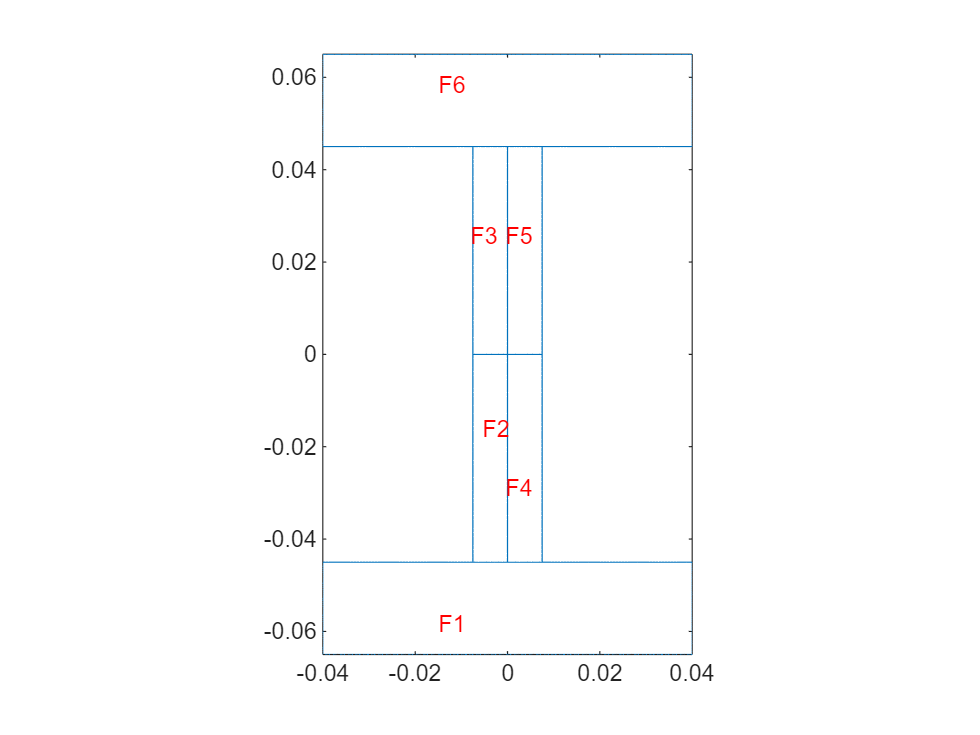

geom_matrix = [R1, R2, R3, R4, R5, R6];
g = decsg(geom_matrix);
gm2D = fegeometry(g);

pdegplot(gm2D,FaceLabels="on")

Construct the 3-D beam by extruding the 2-D cross-section along the total length of the wing spar. Use a vector to specify the height of the extrusion to create multiple sections along the beam's span. Here, the `numSections` variable controls the number of extrusions.

numSections = 10;
extrusions = (spanOfBeam/numSections)*ones(numSections,1);
gm = extrude(gm2D,extrusions);

The `extrude` function always extrudes a 2-D geometry along the *z*-axis. Rotate the beam so that its span aligns with the *y*-axis and deflection aligns with the *z*-axis to match the typical orientation used in wing analysis.

gm = rotate(gm,-90,[0,0,0],[1,0,0]);

Plot the 3-D geometry.

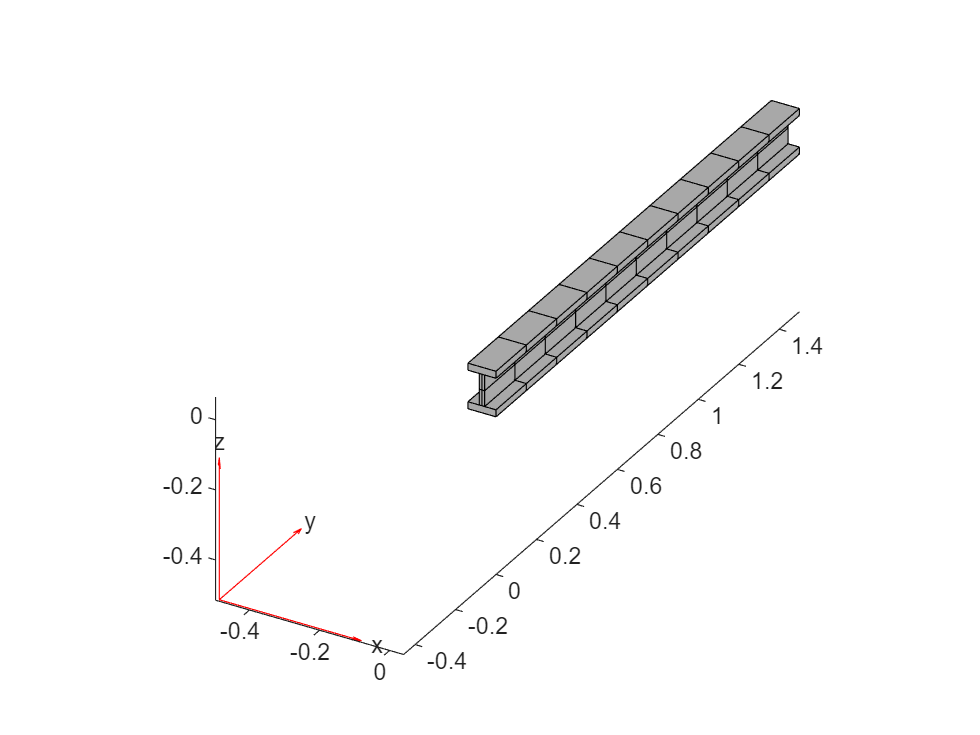

figure
pdegplot(gm)

## Identify Interfaces to Retain in Craig-Bampton Reduction

The Craig-Brampton method computes the modal decomposition of the system and retains some of the physical DoFs in the finite element model. For this example, specify several interface locations where the degrees of freedom (DoFs) are available in the reduced model as physical DoFs for applying loads and boundary conditions. The Craig-Bampton reduction process condenses the remaining DoFs into a few fixed interface modes. In this example, retain one vertex per section at the center of the I-beam to apply lift and drag loads. Additionally, keep a pair of vertices at each section to facilitate the application of twisting moments to the beam. Avoid the fixed end (y = 0) vertices by imposing y > 0.

Locate the vertices at the center of the sections using the coordinates *x* = 0 and *z* = 0. 

centerVertexIDs = find(abs(gm.Vertices(:,1))<eps & abs(gm.Vertices(:,3))<eps & abs(gm.Vertices(:,2))>0);

Locate the vertices at the fore and aft of the midline of the web by using *x *= `w_sub` and *x* =`-tw_sub`, respectively, and *z* = 0.

webFwdVertexIDs = find(abs(gm.Vertices(:,1)-tw_sub)<eps & abs(gm.Vertices(:,3))<eps & abs(gm.Vertices(:,2))>0);
webAftVertexIDs = find(abs(gm.Vertices(:,1)+tw_sub)<eps & abs(gm.Vertices(:,3))<eps & abs(gm.Vertices(:,2))>0);

Locate the vertices on the fixed end.

fixedBCVertexIDs = find(abs(gm.Vertices(:,2))<eps);

Plot the locations of the retained vertices. The red center vertices are where drag and lift forces are applied. The twisting moment is simulated by applying equal and opposite forces at the green aft and blue fwd locations.

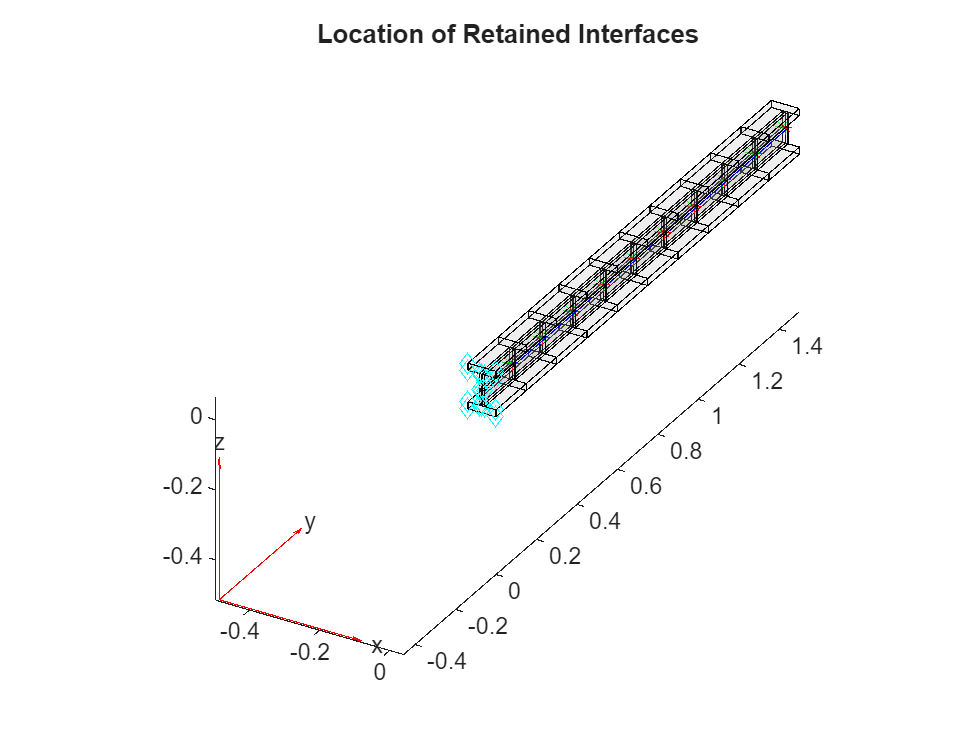

figure
pdegplot(gm,FaceAlpha=0.1)
hold on
markVertices = @(gm,vertexIDs,markerSpec) plot3(gm.Vertices(vertexIDs,1),...
                                            gm.Vertices(vertexIDs,2),...
                                            gm.Vertices(vertexIDs,3),markerSpec);
markVertices(gm,webFwdVertexIDs,"b");
markVertices(gm,webAftVertexIDs,"g*");
markVertices(gm,centerVertexIDs,"r*");
markVertices(gm,fixedBCVertexIDs,"cd");
title("Location of Retained Interfaces")

## Finite-Element Model Reduction

Create an `femodel` object for transient structural analysis and include the I-beam geometry in the model.

model = femodel(AnalysisType="structuralTransient", ...
                Geometry=gm);

Specify Young's modulus, Poisson's ratio, and the mass density of the material.

model.MaterialProperties = ...
    materialProperties(YoungsModulus=210E9, ...
                       PoissonsRatio=0.3, ...
                       MassDensity=7800);

Generate the mesh.

model = generateMesh(model,Hmax=1);

Define the ROM interfaces using all loaded and fixed vertices.

romIntMid = romInterface(Vertex=...
                        [centerVertexIDs; ...
                         webFwdVertexIDs; ...
                         webAftVertexIDs; ...
                         fixedBCVertexIDs]);

Assign the interface object to the `ROMInterfaces` property of the model.

model.ROMInterfaces = romIntMid;

Reduce the structure, retaining all fixed interface modes up to 10000.

ROM = reduce(model,FrequencyRange=[-inf,10000]);

## Reduced Mass and Stiffness Matrices

Simulating transient dynamics in Simulink® requires applying proper constraints to the reduced mass and stiffness matrices available in the ROM to prevent rigid body motion. Additionally, we must identify the locations of various DoFs in the constrained ROM to apply loads and extract displacement from the solution.

To assist with this bookkeeping, first create a function to retrieve the finite-element DoFs based on geometric vertex IDs.

getFEDoFForVertex = @(msh,vertexIDs) findNodes(msh,'region',Vertex=vertexIDs)' +[0,1,2]*size(msh.Nodes,2);

The function `getFEDoFForVertex` returns a matrix with three columns, each corresponding to a spatial direction (x, y, z). Use this function to obtain the finite-element DoFs for all vertices of interest:

centerDoFs = getFEDoFForVertex(ROM.Mesh, centerVertexIDs);
webFwdDoFs = getFEDoFForVertex(ROM.Mesh, webFwdVertexIDs);
webAftDoFs = getFEDoFForVertex(ROM.Mesh, webAftVertexIDs);
fixedDoFs = getFEDoFForVertex(ROM.Mesh, fixedBCVertexIDs);

Apply the fixed BC by eliminating those DoFs from the ROM to obtain a properly constrained ROM system. 

unconstrainedDOF = find(~ismember(ROM.RetainedDoF,fixedDoFs(:)));
modalDoF = numel(ROM.RetainedDoF) + (1:ROM.NumModes);
sysDof = [unconstrainedDOF; modalDoF'];
Kconstrained = ROM.K(sysDof, sysDof);
Mconstrained = ROM.M(sysDof, sysDof);

Next, construct a dictionary to map all finite-element DoFs to their locations in the constrained ROM matrices, which already excludes the `fixedDoF`. This dictionary will assist in locating the DoFs corresponding to `centerDoF, webFwdDoF,` and `webAftDoF` in the constrained ROM for load application.

ROMDoFs = setdiff(ROM.RetainedDoF, fixedDoFs(:));
MapROMDoF2Index = dictionary(ROMDoFs', 1:numel(ROMDoFs));

Identify the locations of the DoFs corresponding to drag, lift, and twisting loads in the ROM.

centerDoFROMIdx = MapROMDoF2Index(centerDoFs);
webFwdDoFROMIdx = MapROMDoF2Index(webFwdDoFs);
webAftDoFROMIdx = MapROMDoF2Index(webAftDoFs);
DragDoFROMIdx = centerDoFROMIdx(:, 1);
LiftDoFROMIdx = centerDoFROMIdx(:, 3);
fwdXROMIdx = webFwdDoFROMIdx(:,1);
fwdZROMIdx = webFwdDoFROMIdx(:,3);
aftXROMIdx = webAftDoFROMIdx(:,1);
aftZROMIdx = webAftDoFROMIdx(:,3);

Apply damping and expand the second-order in time system to a first-order system. Construct the reduced mass and stiffness matrices, `Mode` and `Kode`, to use in Simulink model. 

alpha = 0.001;
beta = 0.1;
nDoF = size(Mconstrained,1);
Mode = [speye(nDoF,nDoF),sparse(nDoF,nDoF); ...
        alpha*Mconstrained+beta*Kconstrained,Mconstrained];
Kode = [sparse(nDoF,nDoF),-speye(nDoF,nDoF); ...
        Kconstrained,sparse(nDoF,nDoF)];

## Aerodynamic Loading

In Simulink model, use the aerodynamic lift, drag, and moment coefficients to provide force inputs to the finite-element model at discrete locations along the span-wise locations. The aerodynamic forces and moments are coupled with the structural dynamics because the deformation of the wing causes a change in the air flowing around the wing. Feed the deformation of the finite-element model back into the aerodynamic calculations to capture this aeroelastic phenomenon.

The forces generated in the area between these stations are concentrated at a point load at the quarter chord location, according to the conventions of aerodynamic coefficients. Simulink calculates the aerodynamic forces and moments using these equations.


$$\textrm{Force}=\frac{1}{2}\rho V_{\infty }^2 S\;C$$
                                                      
$$\textrm{Moment}=\frac{1}{2}\rho V_{\infty }^2 S\;c\;C$$


Here, $\rho$ is the air density, $V_{\infty }$is the airspeed, *S* is the wing area, *C* is the aerodynamic coefficient, and *c* is the chord length.

Define the parameters for the Simulink model.

nStations = length(find(aftZROMIdx));
AEROELASTIC = 1; % turn deformation on/off in model
chord = 1.0;
areas = chord*extrusions;
rho = 1.225;

The Simulink model uses the aerodynamic coefficients in a LUT with angle of attack as the query variable. Apply loads and read deformation in 10 span locations. The axis conventions have the air flowing over the wing in the positive `x`-direction and a positive moment corresponds to a node-up pitching moment.

data = readmatrix('airfoil_coeffs.csv');
coeffs = data(:,[1:3 5]); % save only lift, drag, moment

Each span-wise location has four inputs and four outputs. Defined them in the order in which they are used in Simulink. Construct the moment at each station by applying two forces on the beam model, but in opposite directions. Apply the forces at the same distances from the axis of rotation (the y-axis): one force is at a negative and another at a positive *x*-location. The forces have equal magnitudes in the `z`-direction: one is in the positive and another in the negative *z*-direction .

#### Input

- Lift force (*z*-direction)

- Drag force (*x*-direction)

- Forward component of moment (positive *x*-location)

- Aft component of moment (negative *x*-location)

inIdx = [LiftDoFROMIdx,DragDoFROMIdx, ...
         fwdZROMIdx,aftZROMIdx]';
inIdx = inIdx(:);

#### Output

- Forward *x*-deflection

- Aft *x*-deflection

- Forward *z*-deflection

- Aft *z*-deflection

outIdx = [fwdXROMIdx,aftXROMIdx, ...
          fwdZROMIdx,aftZROMIdx]';
outIdx = outIdx(:);

Plot the cross-section of the l-beam and indicate the lift and drag forces acting on the center location of the cross-section by a red circle. Indicate the mesh nodes corresponding to the moment forces and the deflection outputs by the red asterisks on the edge of the web of the cross-section.

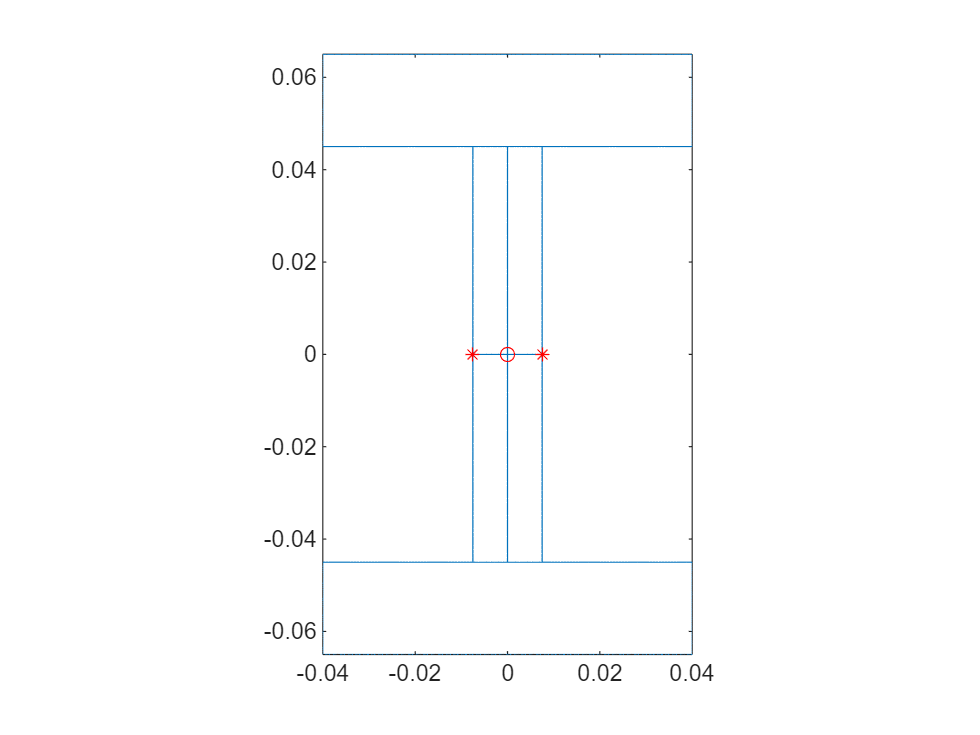

figure
pdegplot(gm2D)
hold on
plot(0,0,"ro")
plot([-tw_sub,tw_sub],[0,0],"r*")
hold off

Organize the input and output vectors to stack the four data points at each span location on top of each other. The following `B` matrices of the DSS system ensure that you apply the input forces at the correct state indexes.

nOut = length(outIdx);
nIn = length(inIdx);

Bbot = sparse(nDoF,nIn);
Bbot(inIdx' + (0:nDoF:((nIn-1)*nDoF))) = 1;
Brom = [sparse(nDoF,nIn); Bbot];

Create the `C` matrix so that the system only outputs the necessary deflection information.

Ctop = sparse(nDoF,nOut);
Ctop(outIdx' + (0:nDoF:((nOut-1)*nDoF))) = 1;
Crom = [Ctop; sparse(nDoF,nOut)]';

Create a function to save the test parameters and maximum deflection to the SimulationOutput object.

function out = postsim(out,aoa,q)
    out.deflection = out.yout(end);
    out.AOA = aoa;
    out.q = q;
end

With the system defined, run the model across a sweep of operating conditions that vary angle of attack and freestream air velocity.

mdl = 'aeroelastic_feedback';
sweepAOA = -16.75:19.25;
sweepVinf = 100:50:250;

clear in
in(1:numel(sweepAOA)*numel(sweepVinf)) = Simulink.SimulationInput(mdl);
in = reshape(in,numel(sweepAOA),numel(sweepVinf));

for i = 1:numel(sweepAOA)
    for j = 1:numel(sweepVinf)
        aoai = sweepAOA(i);
        qi = 0.5*rho*sweepVinf(j)*sweepVinf(j);
        in(i,j) = setBlockParameter(in(i,j), ...
            'aeroelastic_feedback/AOA wrt Root',...
            'Bias',num2str(aoai));
        in(i,j) = setBlockParameter(in(i,j), ...
            'aeroelastic_feedback/Apply aerodynamic loads and moments/Dynamic Presssure (q)', ...
            'Gain',num2str(qi));

[18-Nov-2024 11:03:47] Checking for availability of parallel pool...
[18-Nov-2024 11:03:47] Starting Simulink on parallel workers...
[18-Nov-2024 11:03:49] Configuring simulation cache folder on parallel workers...
[18-Nov-2024 11:03:49] Transferring base workspace variables used in the model to parallel workers...
[18-Nov-2024 11:03:49] Total size of base workspace variables to send to parallel workers is 22.86 MB.
[18-Nov-2024 11:03:52] Loading model on parallel workers...
[18-Nov-2024 11:03:56] Running simulations...
[18-Nov-2024 11:03:58] Completed 1 of 148 simulation runs
[18-Nov-2024 11:03:58] Received simulation output (size: 98.78 KB) for run 1 from parallel worker.
[18-Nov-2024 11:03:58] Completed 2 of 148 simulation runs
[18-Nov-2024 11:03:58] Received simulation output (size: 100.19 KB) for run 2 from parallel worker.
[18-Nov-2024 11:03:58] Completed 3 of 148 simulation runs
[18-Nov-2024 11:03:58] Received simulation output (size: 100.19 KB) for run 3 from parallel worker.
[

        in(i,j) = setPostSimFcn(in(i,j), @(x) postsim(x,aoai,qi));
    end
end

out = parsim(in,TransferBaseWorkspaceVariables="on");

Plot the maximum deflection of each test point by using the `SimulationOutput` object.

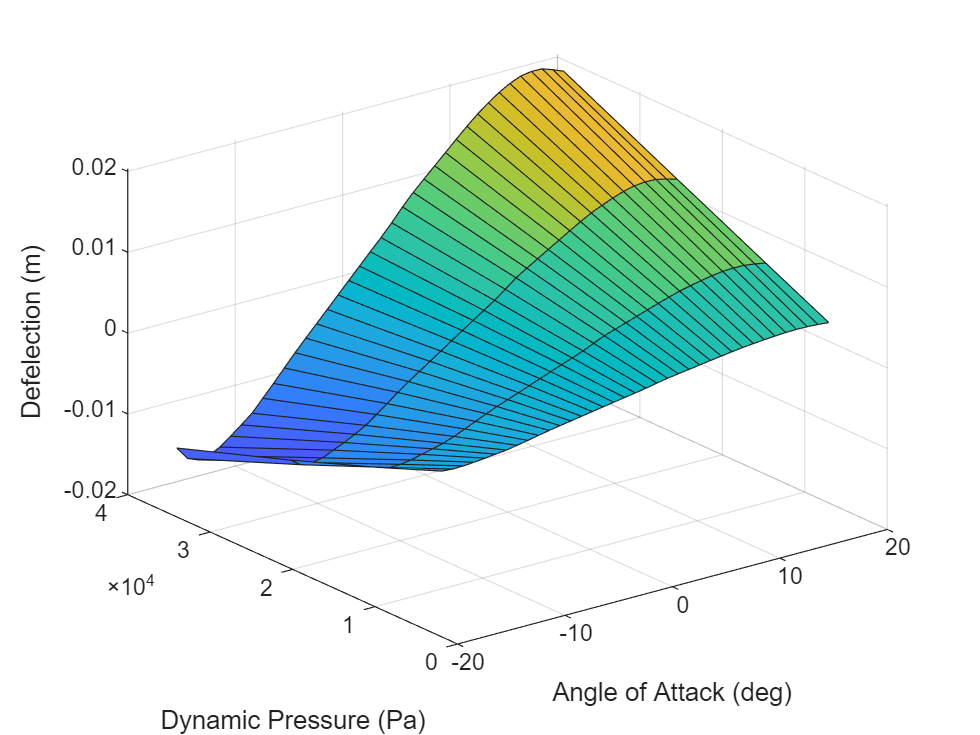

X = zeros(size(out));
Y = zeros(size(out));
Z = zeros(size(out));

for i = 1:size(out,1)
    for j = 1:size(out,2)
        X(i,j) = out(i,j).AOA;
        Y(i,j) = out(i,j).q;
        Z(i,j) = out(i,j).deflection;
    end
end



surf(X,Y,Z);
xlabel("Angle of Attack (deg)"); ylabel("Dynamic Pressure (Pa)"); zlabel("Defelection (m)")
openSimulationManager(in,out)

When the sweep in concluded, the highest stress operating condition is found. You can use these operating conditions as input to the high fidelity finite-element solver and run the analysis to determine the efficacy of the wing spar.

### Run the full-order FE model for maximum deflection load case.

Find the index of maximum deflection loading and apply those loads. Note that aeroelastic coupling affects the load, so you must fetch the coupled load from the Simulink output and apply it to all stations of the model.

[v,idx] = max(Z,[],"all");

maxAOA = X(idx);
maxDynamicPresssure = Y(idx);

stations = numel(extrusions);
AeroDynamicLoad = out(idx).logsout{1}.Values.Data(end,:);
AeroDynamicLoad = reshape(AeroDynamicLoad,[],stations);

The AeroDynamicLoad matrix includes lift in the first row, drag in the second row, and the couple forming the twisting moment in the last two rows. The number of columns corresponds to the number of stations.

LiftForce = AeroDynamicLoad(1,:);
DragForce = AeroDynamicLoad(2,:);
MomentCoupleFwd = AeroDynamicLoad(3,:);
MomentCoupleAft = AeroDynamicLoad(4,:);

In the PDE Toolbox, apply the force as a three-element vector at each vertex. First, construct a 3-by-number-of-stations matrix to apply at three sets of vertices: the center of the station, and the forward and aft vertices at the mid-web section.

centerVerticesForce(1,:) = DragForce;
centerVerticesForce(3,:) = LiftForce;
webFwdVerticesForce(3,:) = MomentCoupleFwd;
webAftVerticesForce(3,:) = MomentCoupleAft;

Note that unassigned rows will default to zero values in the above assignments. Loop through the columns to apply the force vector at three set of vertices at each station.

for i = 1:stations
    model.VertexLoad(centerVertexIDs(i)) = vertexLoad(Force=centerVerticesForce(:,i));
    model.VertexLoad(webFwdVertexIDs(i)) = vertexLoad(Force=webFwdVerticesForce(:,i));
    model.VertexLoad(webAftVertexIDs(i)) = vertexLoad(Force=webAftVerticesForce(:,i));
end

Before simulating the full-order model, apply the fixed constraint and specify the damping parameters.

model.VertexBC(fixedBCVertexIDs) = vertexBC(Constraint="fixed");
model.DampingAlpha = alpha;
model.DampingBeta = beta;

Solve the model.

tlist = 0:0.01:1;
Rtransient = solve(model,tlist);

Compare the bending deflection at the wing-tip obtained with the full-order model to that of ROM simulated in Simulink.

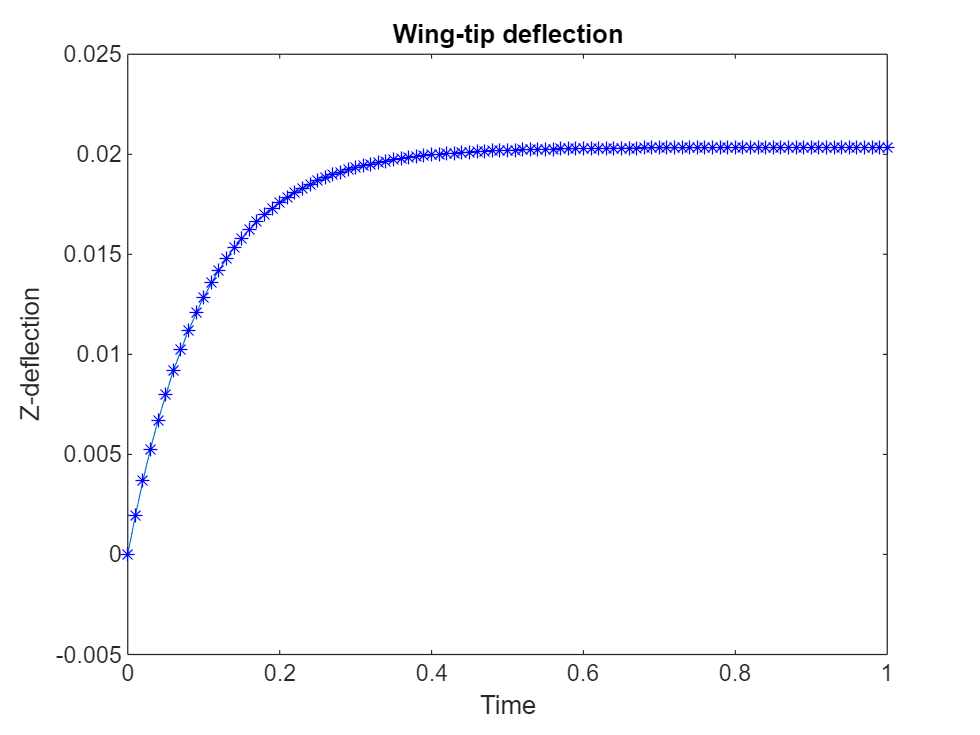

figure
plot(out(idx).tout,out(idx).yout)
hold on
nodeAtWingTipWebAft = getFEDoFForVertex(model.Mesh,webAftVertexIDs(end));
plot(Rtransient.SolutionTimes,Rtransient.Displacement.uz(nodeAtWingTipWebAft(:,1),:),'b*')
title("Wing-tip deflection")
xlabel("Time")
ylabel("Z-deflection")

The full-order model solution can also compute stresses in the model. Compute and plot the von Mises stress.

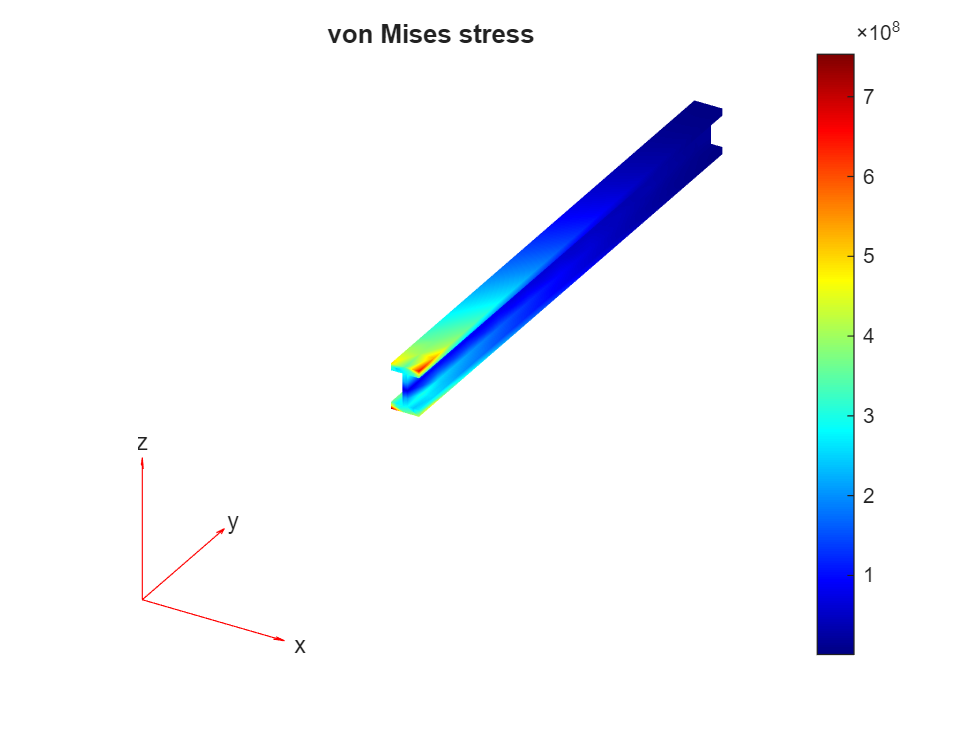

figure
VMstress = Rtransient.evaluateVonMisesStress;
pdeplot3D(model.Mesh,ColorMapData=VMstress(:,end))
title("von Mises stress")

*Copyright 2024 The MathWorks, Inc.*